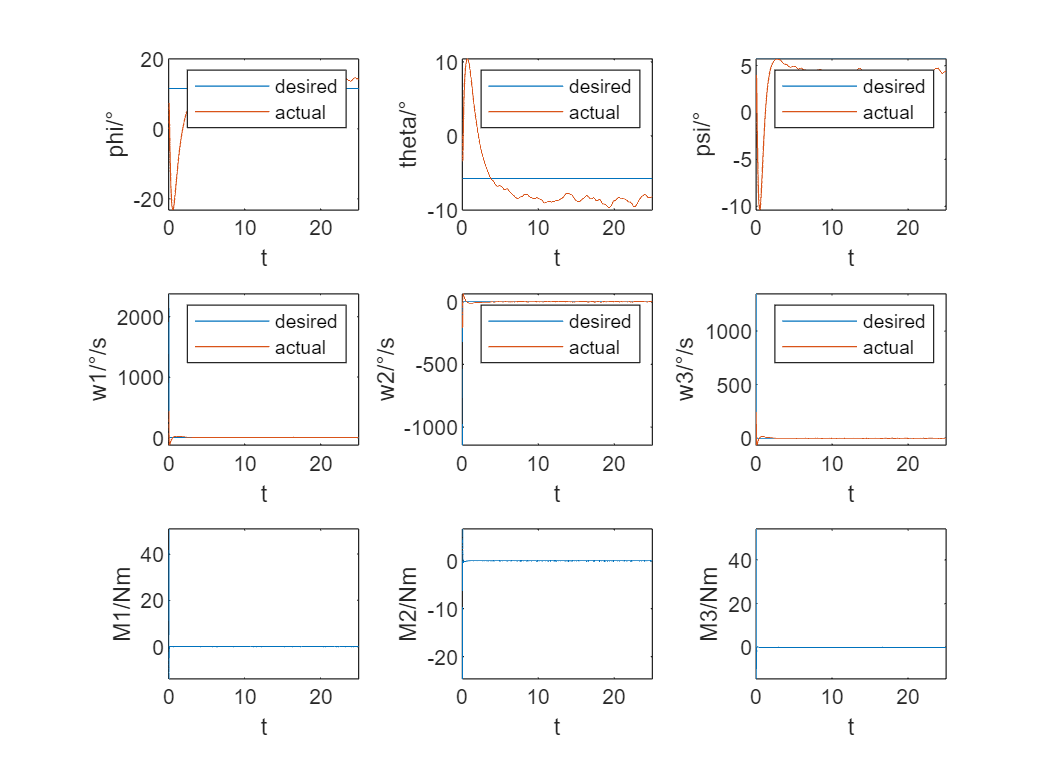

clear;
% Parameters
fs = 200; % Control frequency in Hz
dt = 1/fs;
T = 25; % Total simulation time in seconds
t = 0:1/fs:T; % Time vector
w_mea=0.00004;
M_proc=0.00001;
R_mea=0.04;
wrapToPi = @(angle) mod(angle + pi, 2*pi) - pi;


Rd = zeros(3, 3, length(t));
for i = 1:length(t)
    Rd(:, :, i) = eul2rotm([0.1,-0.1,0.2]);
end

eul=rotm2eul(Rd);
Rd3=eul(:,1);
Rd2=eul(:,2);
Rd1=eul(:,3);

Rd1 = wrapToPi(Rd1);
Rd2 = wrapToPi(Rd2);
Rd3 = wrapToPi(Rd3);

Rd_in= [t', reshape(permute(Rd, [3, 1, 2]), [], 9)];
J=diag([0.029 0.029 0.055]);

A=[zeros(3,3),eye(3);zeros(3,6)];
B=[zeros(3,3);eye(3)];


% 指定的新极点位置
desired_poles = [-2, -2, -1, -3, -1, -3];

% 设计状态反馈控制律
K = place(A, B, desired_poles);


sim("atti.slx")

subplot(3,3,1)
plot(t, Rd1 * 180/pi, tout, outa(:,1) * 180/pi)
legend('desired','actual');
xlabel('t'); ylabel('phi/°');

subplot(3,3,2)
plot(t, Rd2 * 180/pi, tout, outa(:,2) * 180/pi)
legend('desired','actual');
xlabel('t'); ylabel('theta/°');

subplot(3,3,3)
plot(t, Rd3 * 180/pi, tout, outa(:,3) * 180/pi)
legend('desired','actual');
xlabel('t'); ylabel('psi/°');

subplot(3,3,4)
plot(t, wd1 * 180/pi, tout, outw(:,1) * 180/pi)
legend('desired','actual');
xlabel('t'); ylabel('w1/°/s');

subplot(3,3,5)
plot(t, wd2 * 180/pi, tout, outw(:,2) * 180/pi)
legend('desired','actual');
xlabel('t'); ylabel('w2/°/s');

subplot(3,3,6)
plot(t, wd3 * 180/pi, tout, outw(:,3) * 180/pi)
legend('desired','actual');
xlabel('t'); ylabel('w3/°/s');

subplot(3,3,7)
plot(tout,outM(:,1));
xlabel('t'); ylabel('M1/Nm');

subplot(3,3,8)
plot(tout,outM(:,2));
xlabel('t'); ylabel('M2/Nm');

subplot(3,3,9)
plot(tout,outM(:,3));
xlabel('t'); ylabel('M3/Nm');